% TODOS:
% Implement MSER

reference = rgb2gray(imread("images\box.jpg"));
target = rgb2gray(imread("images\scene.jpg"));
% Crop reference Image
tmp = imshow(reference);
roi = drawrectangle;
reference = imcrop(reference,roi.Position);
tmp.Visible = false;
close all;
clf;

 ;
detectionMethod = "BRISK";

% Which feature detection to use?
switch detectionMethod
    case "BRISK"
        referencePoints = detectBRISKFeatures(reference);
        targetPoints = detectBRISKFeatures(target);
    case "FAST"
        referencePoints = detectFASTFeatures(reference);
        targetPoints = detectFASTFeatures(target);
    case "Harris"
        referencePoints = detectHarrisFeatures(reference);
        targetPoints = detectHarrisFeatures(target);
    case "MinEigen"
        referencePoints = detectMinEigenFeatures(reference);
        targetPoints = detectMinEigenFeatures(target);
    case "MSER"
        referencePoints = detectMSERFeatures(reference);
        targetPoints = detectMSERFeatures(target);
    case "ORB"
        referencePoints = detectORBFeatures(reference);
        targetPoints = detectORBFeatures(target);
    case "SURF"
        referencePoints = detectSURFFeatures(reference);
        targetPoints = detectSURFFeatures(target);
    case "KAZE"
        referencePoints = detectKAZEFeatures(reference);
        targetPoints = detectKAZEFeatures(target);
end

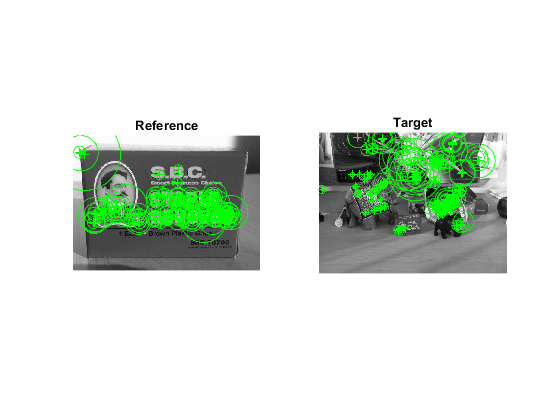

subplot(1,2,1)
imshow(reference);
hold on;
title('Reference');
plot(selectStrongest(referencePoints, 150));
hold off;

subplot(1,2,2)
imshow(target);
hold on;
title('Target');
plot(selectStrongest(targetPoints, 150));
hold off;

[referenceFeatures, referencePoints] = extractFeatures(reference, referencePoints);
[targetFeatures, targetPoints] = extractFeatures(target, targetPoints);

pairs = matchFeatures(referenceFeatures, targetFeatures);
matchedReferencePoints = referencePoints(pairs(:, 1), :);
matchedTargetPoints = targetPoints(pairs(:, 2), :);

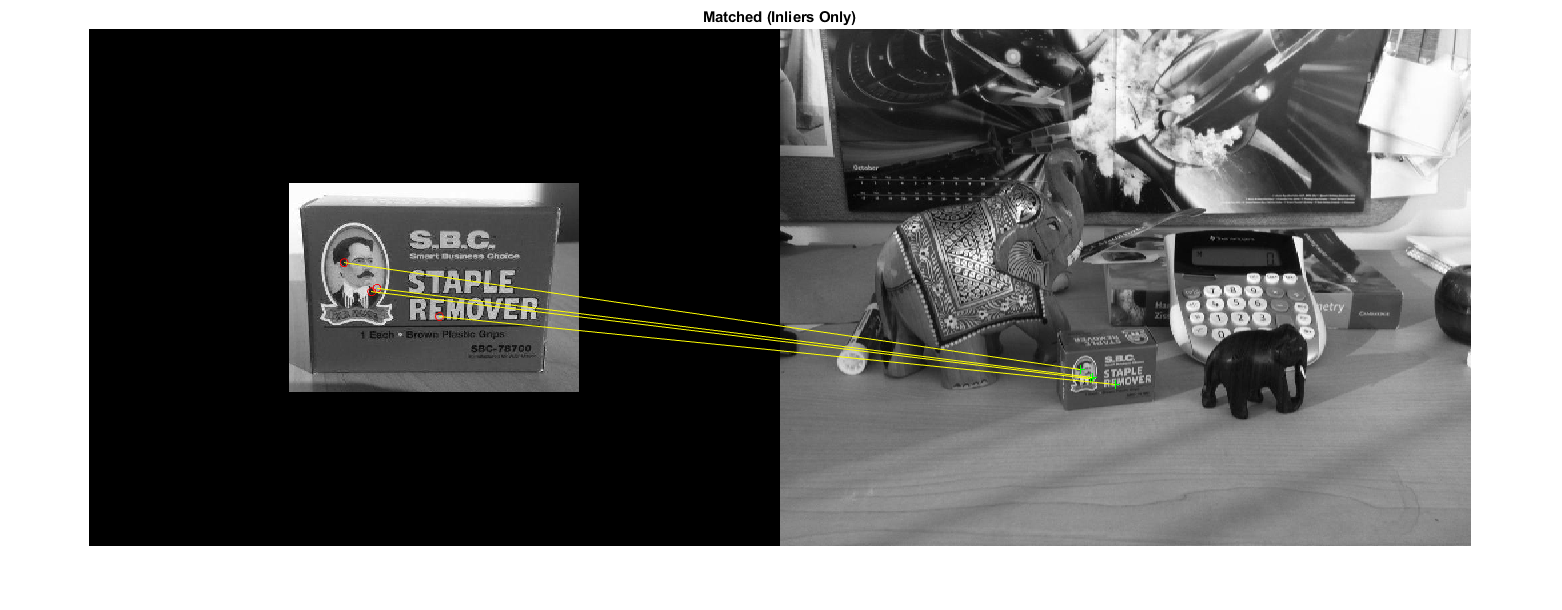

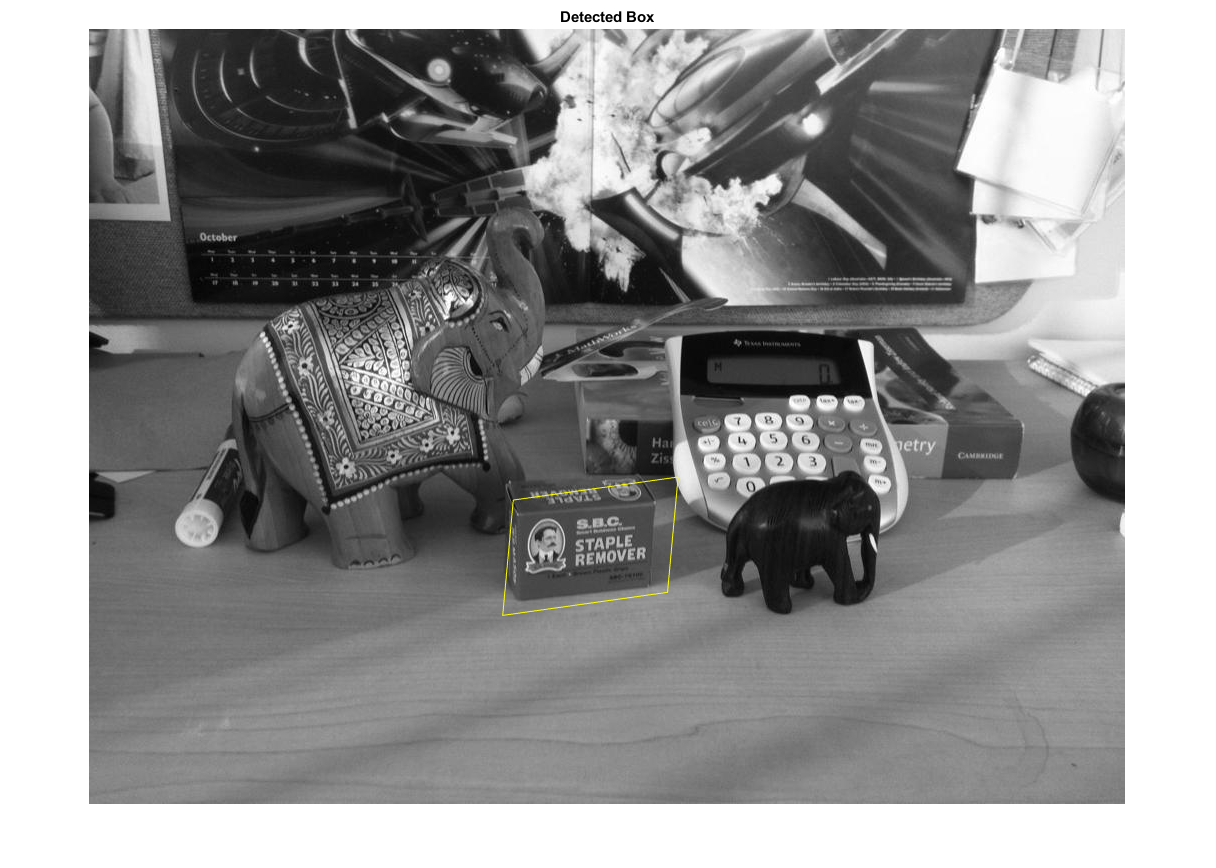

if((matchedTargetPoints.length > 2) && (matchedReferencePoints.length > 2))
    [tform, estimatedReferencePoints, estimatedTargetPoints] = ...
        estimateGeometricTransform(matchedReferencePoints, matchedTargetPoints, 'affine');
    
    figure;
    showMatchedFeatures(reference, target, estimatedReferencePoints, ...
        estimatedTargetPoints, 'montage');
    title('Matched (Inliers Only)');
    
    foundPolygon = [1, 1;...                                    % top-left
                size(reference, 2), 1;...                    % top-right
                size(reference, 2), size(reference, 1);...    % bottom-right
                1, size(reference, 1);...                    % bottom-left
                1, 1];                                      % top-left again to close the polygon

    newFoundPolygon = transformPointsForward(tform, foundPolygon);
    
    figure;
    imshow(target);
    hold on;
    line(newFoundPolygon(:, 1), newFoundPolygon(:, 2), 'Color', 'y');
    title('Detected Box');
    hold off;
else
    disp("Not enough features found for matching.")
end